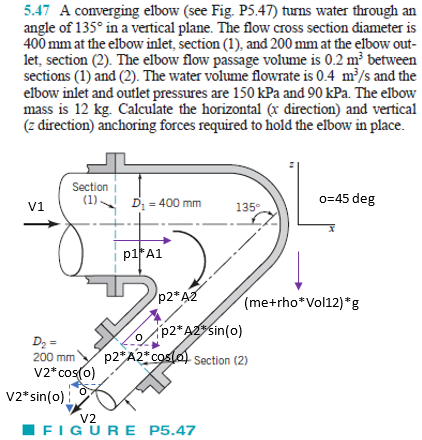

# constants

u = symunit;
Q = 0.4*u.m^3/u.s;
me = 12*u.kg;
rho = 1000*u.kg/u.m^3;
Vol12 = 0.2*u.m^3;
g = 9.81*u.m/u.s^2;
theta = 45*u.deg;

# inflow properties

p1 = 150*u.kPa;
D1 = 400*u.mm;
A1 = sympi*D1^2/4;
V1 = rewrite(Q/A1, 'SI');
V1x = V1;
V1z = 0;
mdot1 = rewrite(rho*A1*V1, 'SI');

# outflow properties

p2 = 90*u.kPa;
D2 = 200*u.mm;
A2 = sympi*D2^2/4;
V2 = rewrite(Q/A2, 'SI');
V2x = V2*cos(theta);
V2z = V2*sin(theta);
mdot2 = rewrite(rho*A2*V2, 'SI');

# conservation of momentum (x-direction)

syms Fx;
Fx = solve(Fx+p1*A1+p2*A2*cos(theta) == -mdot1*(V1x)+mdot2*(-V2x));
Fx = rewrite(simplify(Fx), u.kN);
Fx_vpa = vpa(Fx, 4) %#ok

$$Fx\_vpa = -25.72\,\mathrm{kN}$$

clear Fx_vpa;

# conservation of momentum (z-direction)

syms Fz;
Fz = solve(Fz+p2*A2*sin(theta)-(me+rho*Vol12)*g == -mdot1*(V1z)+mdot2*(-V2z));
Fz = rewrite(simplify(Fz), u.kN);
Fz_vpa = vpa(Fz, 3) %#ok

$$Fz\_vpa = -3.52\,\mathrm{kN}$$

clear Fz_vpa;